# QEA 3: Navigating the Gauntlet Using Gradient Descent

Dongim Lee, Isabelle Rodriguez

## Overview:

Our goal was to have the neato move from the origin to the Ball of Benevolence without running into obstacles. We used the neato’s LIDAR scanner to scan and create a map of the gauntlet by translating and rotating the scan data into the global coordinate frame. We took this new data and fitted a circle to the Ball of Benevolence, and found the coordinates of the center. This would become the center of the circular sink in our potential field. For the walls, we went through our data (global frame) and wrote a function to detect the end points of each wall, then we got the points in between each end point. These points would be our sources. 

To get our potential field we used the following equations for our sources and sinks (respectively):


$$V\left(x,y\right)=-\ln \left(\sqrt{{\left(x-a\right)}^2 +{\left(y-b\right)}^2 }\right)$$



$$V\left(x,y\right)=\ln \left(\sqrt{{\left(x-a\right)}^2 +{\left(y-b\right)}^2 }\right)$$


To get our gradient we used MATLAB’s built-in *gradient *function and plotted it using *quiver*. We then implemented our gradient descent algorithm with a step size of 0.1. 

## Mapping and Path Planning:

#### A Map of the Gauntlet Using LIDAR Scan Data

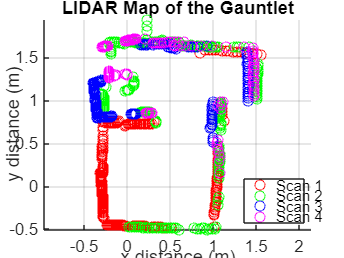

plotGauntletMap("LIDARdata");

#### Potential Fields

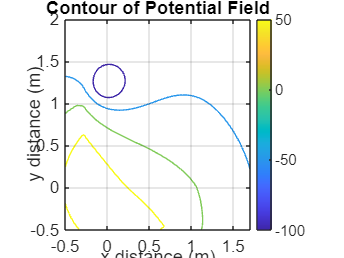

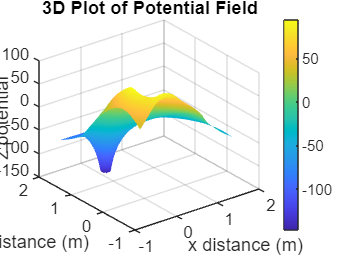

[x, y] = getCoordinatesScanData("LIDARdata");
circle = detectCircle(x, y);
walls = detectWalls(x, y);[x_points, y_points] = getWallPoints(walls);
[xPlot, yPlot, z, dx, dy] = getGradient(x_points, y_points, circle);
plotPotentialFields(xPlot, yPlot, z);

#### Quiver Plot

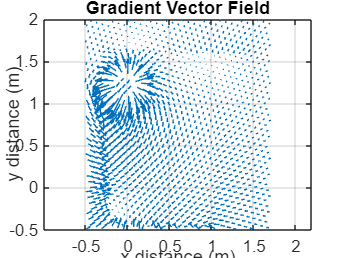

plotQuiverPlot(xPlot, yPlot, dx, dy);

#### A Path of Gradient Descent on Contour

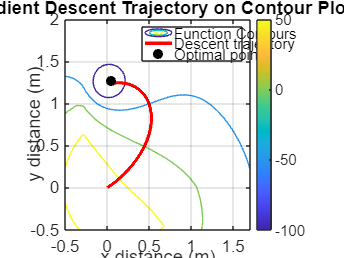

initialPosition = [0; 0];
[trajectory, optimal] = gradientDescent(xPlot, yPlot, z, initialPosition);
plotTrajectory(trajectory, optimal, xPlot, yPlot, z);

## Navigating the Gauntlet:

Our scripts works relatively well. The neato slowly follows the intended path for most of the journey to the BoB without hitting any obstacles. However, instead of stopping at the BoB, it keeps driving for a bit. Other than that though, the neato successfully traverses the Gauntlet to the BoB.

#### A Map of the Gauntlet with Detected Circle and Walls

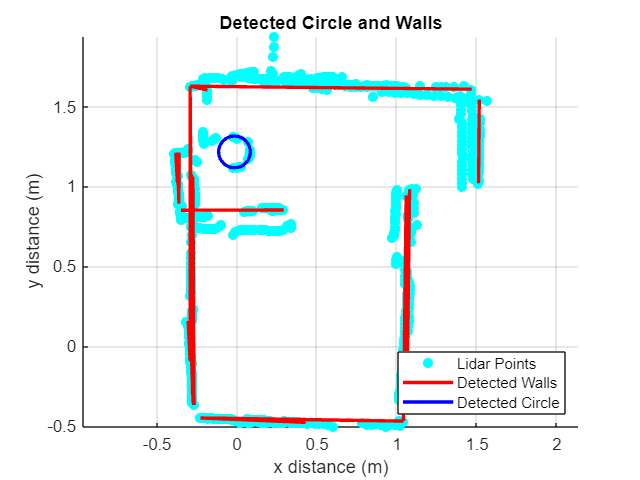

plotDetectedMap(x, y, walls, circle);

#### Intended Path of Gradient Descent

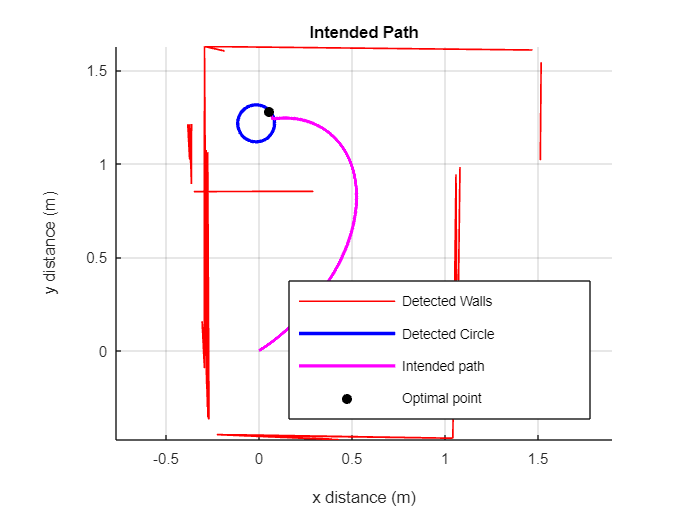

plotIntendedPath(walls, circle, trajectory, optimal);

#### Run Neato

Deleting previous Neato connection.
Connecting to the Neato.
Testing connection.
Connection successful.


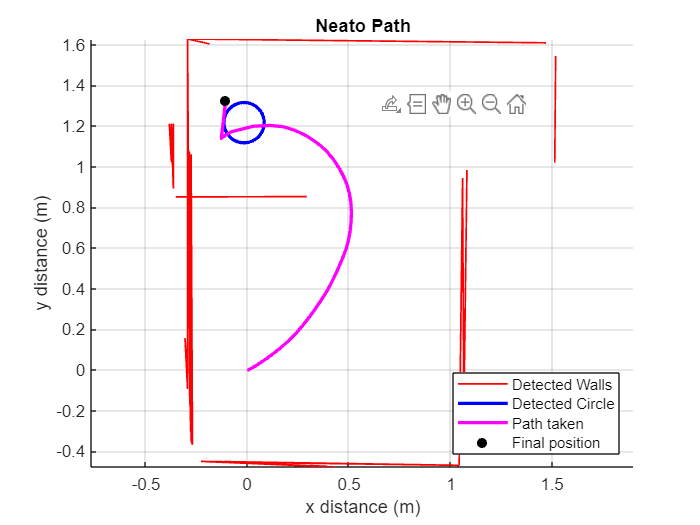

Figure 7. Plot of Neato path from origin to BoB with velocity of 0.03 m/s.


The time took to get to the BoB: 1.132766e+02

The distance the Neato traveled: 2.053500e+00

use_sim = false;
if use_sim == true
    [R, H] = runSimulator(dx, dy, initialPosition, xPlot, yPlot, z);
    plotSimulation(R, walls, circle);
else
    [path, totalTime, totalDistance, encoders, R, H, times] = runRealNeato('192.168.16.90', dx, dy, initialPosition, xPlot, yPlot);
    plotEncoderData(path, walls, circle);
    disp("Figure 7. Plot of Neato path from origin to BoB with velocity of 0.03 m/s.");
    fprintf("The time took to get to the BoB: %d", totalTime);
    fprintf("The distance the Neato traveled: %d", totalDistance);
end

#### Video Link

https://www.youtube.com/watch?v=PZHxOMj1roU

#### Code Link

https://github.com/dongim04/Neato-Gauntlet